# **Miniprojekt C**

## **Formål**

Fra opgavevejledning:

*"Lav i Matlab et system til identifikation af DTMF signaler. Systemet skal kunne reducere forstyrrende elementer i målingen, herunder baggrundsstøj og ”fremmede” enkeltstående frekvenser, - samt fjerne en evt. DC-forskydning.Det er væsentligt, at amplituden på de korrekte frekvenser i signalet ikke ændres nævneværdigt i filtreringsprocesserne."*

*"Der skal i opgaven indgå filtre af begge typer (FIR og IIR), og mindst ét af FIR-filtrene skal designes manuelt vha. vinduesmetoden. Ellers er fir1.m, fir2.m og butter.m i Matlab gode bud på filterdesignfunktioner."*

## **Implementation**

Hver opgave indeholder introduktion, implementation, resultater og diskussion. Resultater er vist under de grå kode blokke.

### P3.13

***Design et 6. ordens båndpas IIR filter (Butterworth). Pasbånd mellem 3kHz og 4kHz, og fs = 24 kHz. Plot og diskuter filterets fasekarakteristik. Bestem filterets group delay (GPD). Plot og diskuter: Hvad sker der ved filtrerets knækfrekvenser? Hvad er max GPD målt i samples, og i millisekunder?***

### P3.14

***Givet det analoge shelving filter beskrevet som Laplace overføringsfunktion nedenfor:***

- ***Bestem vha. bilineær transformation (substitution) den ækvivalente overføringsfunktion H(z)***

- ***Udregn henholdsvis b og a koefficienterne for H(z). Sampletiden Ts sættes til 1 millisekund,  og vinkelfrekvenserne ω1 = 565 rad/s og ω2 = 942 rad/s.***

- ***Vis frekvensresponsen for H(z) vha. ’freqz’  i Matlabd.***

- ***Er H(z) filteret stabilt? Motiver hvorfor eller hvorfor ikke.***

- ***Find differensligningen der repræsenterer H(z), altså y(n) = ...***

### P3.15

***Plot de første 100 samples af impulsresponsen for et højpas IIR filter (Butterworth) med normeret knækfrekvens 0,05 og ordenen sat til henholdsvis 4 og 12. Plot også pol/nulpunkt-placeringerne (’zplane’).***

### **Opgave 1**

***"Studer og dokumenter DTMF princippet og relevante frekvenser."***

**DTMF** står for **d**ual-**t**one **m**ulti-**f**reqency signaling. 

### **Opgave 2**

***"Design og realiser digitale filtre til håndtering af ovennævnte støjproblematikker. Det forventes, at der benyttes forskellige typer filtre til de enkelte opgaver."***

### **Opgave 3**

***"Eksperimenter i opgaven med forskellige filterordener og afskæringsfrekvenser. Dokumenter eksperimenterne og udvælg de ”bedste”."***

### **Opgave 4**

***"Vis udvalgte filtres impulsrespons h(n) og overføringskarakteristik H(m)."***

### **Opgave 5**

***"Vis for ét af filtrene fasekarakteristikken og group delay. Kommenter."***

### **Fjern DC-offset:**

clc
clear
clf
close all;

% loaded file contains freq. sample and the signal
load = load('DTMF_noisy_signal.mat')

load = struct with fields:
    f_sample: 16000
     s_total: [1×52800 double]



% signal variables
fs = load.f_sample % store fs from load

fs = 16000

sig_noisy= load.s_total % store signal samples from load

sig_noisy =     0.9496    2.5253    2.2232    0.9938    2.2088    3.7067    1.8639   -0.9334   -1.2329   -0.0415    0.0531   -0.6644   -0.6899    0.1340    1.7066    3.1578    2.5187   -0.1954   -2.3118   -1.7694    0.4699    1.4110    0.4893    0.2229    1.1692    0.7291   -2.1798   -4.5118   -3.4330   -1.1511   -0.5496   -0.3322    0.5542    2.0349    3.1082    1.1538   -1.1572   -0.1570    0.8247    0.0005   -1.0460   -2.4637   -2.1065    0.6144    1.0407   -0.5235    0.3362    2.6415    2.8318    1.0919


n = length(sig_noisy) % length of signal

n = 52800

freq_res = fs / n % frequency resolution

freq_res = 0.3030


% time axis
Ts = 1/fs % time pr. sample

Ts = 6.2500e-05

Tn = n * Ts % total signal play time

Tn = 3.3000

t = 0:Ts:Tn-Ts % time axis; start 0 and step by Ts untill Tn is reached

t =          0    0.0001    0.0001    0.0002    0.0003    0.0003    0.0004    0.0004    0.0005    0.0006    0.0006    0.0007    0.0008    0.0008    0.0009    0.0009    0.0010    0.0011    0.0011    0.0012    0.0013    0.0013    0.0014    0.0014    0.0015    0.0016    0.0016    0.0017    0.0018    0.0018    0.0019    0.0019    0.0020    0.0021    0.0021    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031



% dc-offset
dc = mean(sig_noisy) % dc offset / mean value

dc = 0.4975

sig_no_offset = sig_noisy - dc % remove dc from signal

sig_no_offset =     0.4522    2.0278    1.7257    0.4963    1.7113    3.2092    1.3664   -1.4309   -1.7303   -0.5390   -0.4444   -1.1619   -1.1874   -0.3635    1.2092    2.6604    2.0213   -0.6929   -2.8093   -2.2669   -0.0275    0.9135   -0.0081   -0.2746    0.6718    0.2316   -2.6773   -5.0092   -3.9305   -1.6486   -1.0470   -0.8296    0.0567    1.5374    2.6108    0.6563   -1.6547   -0.6544    0.3272   -0.4970   -1.5435   -2.9612   -2.6040    0.1169    0.5433   -1.0209   -0.1613    2.1440    2.3343    0.5944


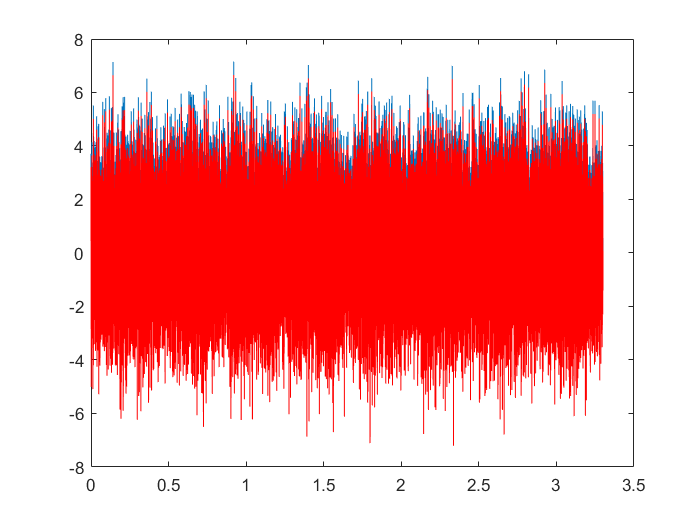


% plot
plot(t,sig_noisy)
hold on
plot(t, sig_no_offset, "r")

## **Konklusion**